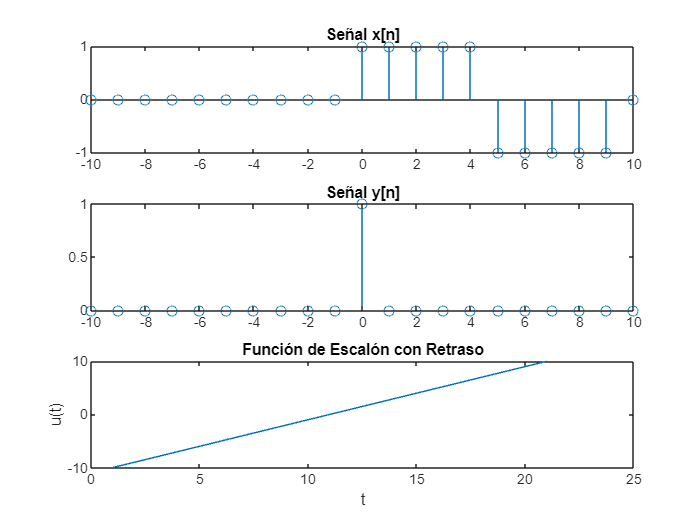

% Ecuación convolución discreta mediante sumatoria
syms k y(n) x(n) h(n)

f = x(k) * h(n - k);
y(n) = subs(f, k, -3:3);
consum = symsum(f, k, -inf, inf)
res = feval(y,3)

%Ecuación de diferencias de coeficientes constantes
syms a(k) b(m) y(n) x(n) m k n M N 
parteA = a(k) * y(n - k + 1);
parteB = b(m) * x(n - m + 1);
resParteA = symsum(parteA, k, 1, M);
resParteB = symsum(parteB, m, 1, N);
res = resParteA - resParteB
resParteA = subs(A,k,-2:2)
resParteB = subs(B,m,-2:2)
res = resParteA - resParteB
evaluacion = subs(res, n, 2)

%Relación entre la señal de salida y la señal de entrada
syms a(k) b(m) y(n) x(n) m k n M N a1
parteB = (b(m)/a1) * x(n - m + 1);
parteA = (a(k)/a1) * y(n - k + 1);
resparteB = subs(parteB, a1, 2); 
resparteA = subs(parteA, a1, 2); 
resparteB1 = subs(resparteB, m, -2:2);
resparteA1 = subs(resparteA, k, -2:2);
y(n) = resparteB1 - resparteA1;
evaluacion = subs(y(n), n, 3)



